# Setup and Variable Parameters

clc
clear

%Plant
Cu = 3.53e3;
Cw = 7.47e2;
I = 1.97e3;
G_plant = tf(Cu,[I Cw 0]);

%Time Vector, delta_t, and Position input (tracking setpoint)
N_temp = 20;
delta_t = 0.0001;
t = 0:delta_t:N_temp;
%V_set = .1*ones(1,size(t,2)); %step
unitstep = t>=0;
V_set = .01*t.*unitstep;

%Parameters
n_delay = 0.2; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .05; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = .5; %Proportional Gain
K_I = 0.01; %Integral Gain of smooth system

V_in = [t' V_set'];

%Simulink Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)


# Simulate

out = sim('HybridSaccadeFF.slx');

Found algebraic loop containing: 
HybridSaccadeFF/Saccade Logic and Memory Layer/Switch1 (discontinuity)
HybridSaccadeFF/Saccade Logic and Memory Layer/Switch3 (discontinuity)
HybridSaccadeFF/Saccade Logic and Memory Layer/Switch2 (discontinuity)
HybridSaccadeFF/Add (algebraic variable)


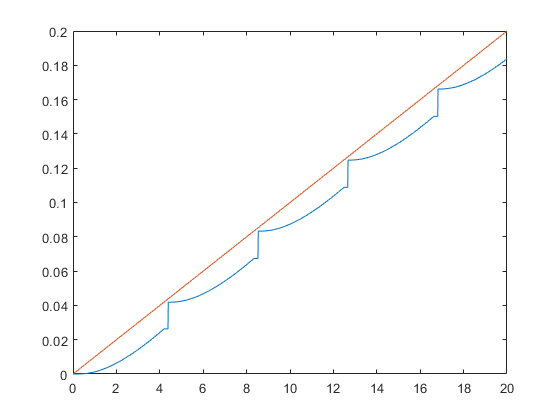


figure
plot(out.tout,out.V_out,t,V_set)